plotindex = 1,   c=1, r=1


plotindex = 2,   c=2, r=1


plotindex = 3,   c=3, r=1


plotindex = 4,   c=4, r=1


plotindex = 5,   c=1, r=2


plotindex = 6,   c=2, r=2


plotindex = 7,   c=3, r=2


plotindex = 8,   c=4, r=2


plotindex = 9,   c=1, r=3


plotindex = 10,   c=2, r=3


plotindex = 11,   c=3, r=3


plotindex = 12,   c=4, r=3


plotindex = 13,   c=1, r=4


plotindex = 14,   c=2, r=4


plotindex = 15,   c=3, r=4


plotindex = 16,   c=4, r=4


image_features = 1×1764 single row vector
    75    74    86   108   146   161   193   177   242    83    80    90   136   190   153   156   207   255    78    86    93   164   192   146   224   255   255    74    91   110   178   184   177   255   255   255    71    96   132   193   195   208   242   255   249    69   120   172   179   187


image_features = 1×1764 single row vector
    75    74    86   108   146   161   193   177   242    83    80    90   136   190   153   156   207   255    78    86    93   164   192   146   224   255   255    74    91   110   178   184   177   255   255   255    71    96   132   193   195   208   242   255   249    69   120   172   179   187


plotindex = 1,   c=1, r=1


plotindex = 2,   c=2, r=1


plotindex = 3,   c=3, r=1


plotindex = 4,   c=4, r=1


plotindex = 5,   c=1, r=2


plotindex = 6,   c=2, r=2


plotindex = 7,   c=3, r=2


plotindex = 8,   c=4, r=2


plotindex = 9,   c=1, r=3


plotindex = 10,   c=2, r=3


plotindex = 11,   c=3, r=3


plotindex = 12,   c=4, r=3


plotindex = 13,   c=1, r=4


plotindex = 14,   c=2, r=4


plotindex = 15,   c=3, r=4


plotindex = 16,   c=4, r=4


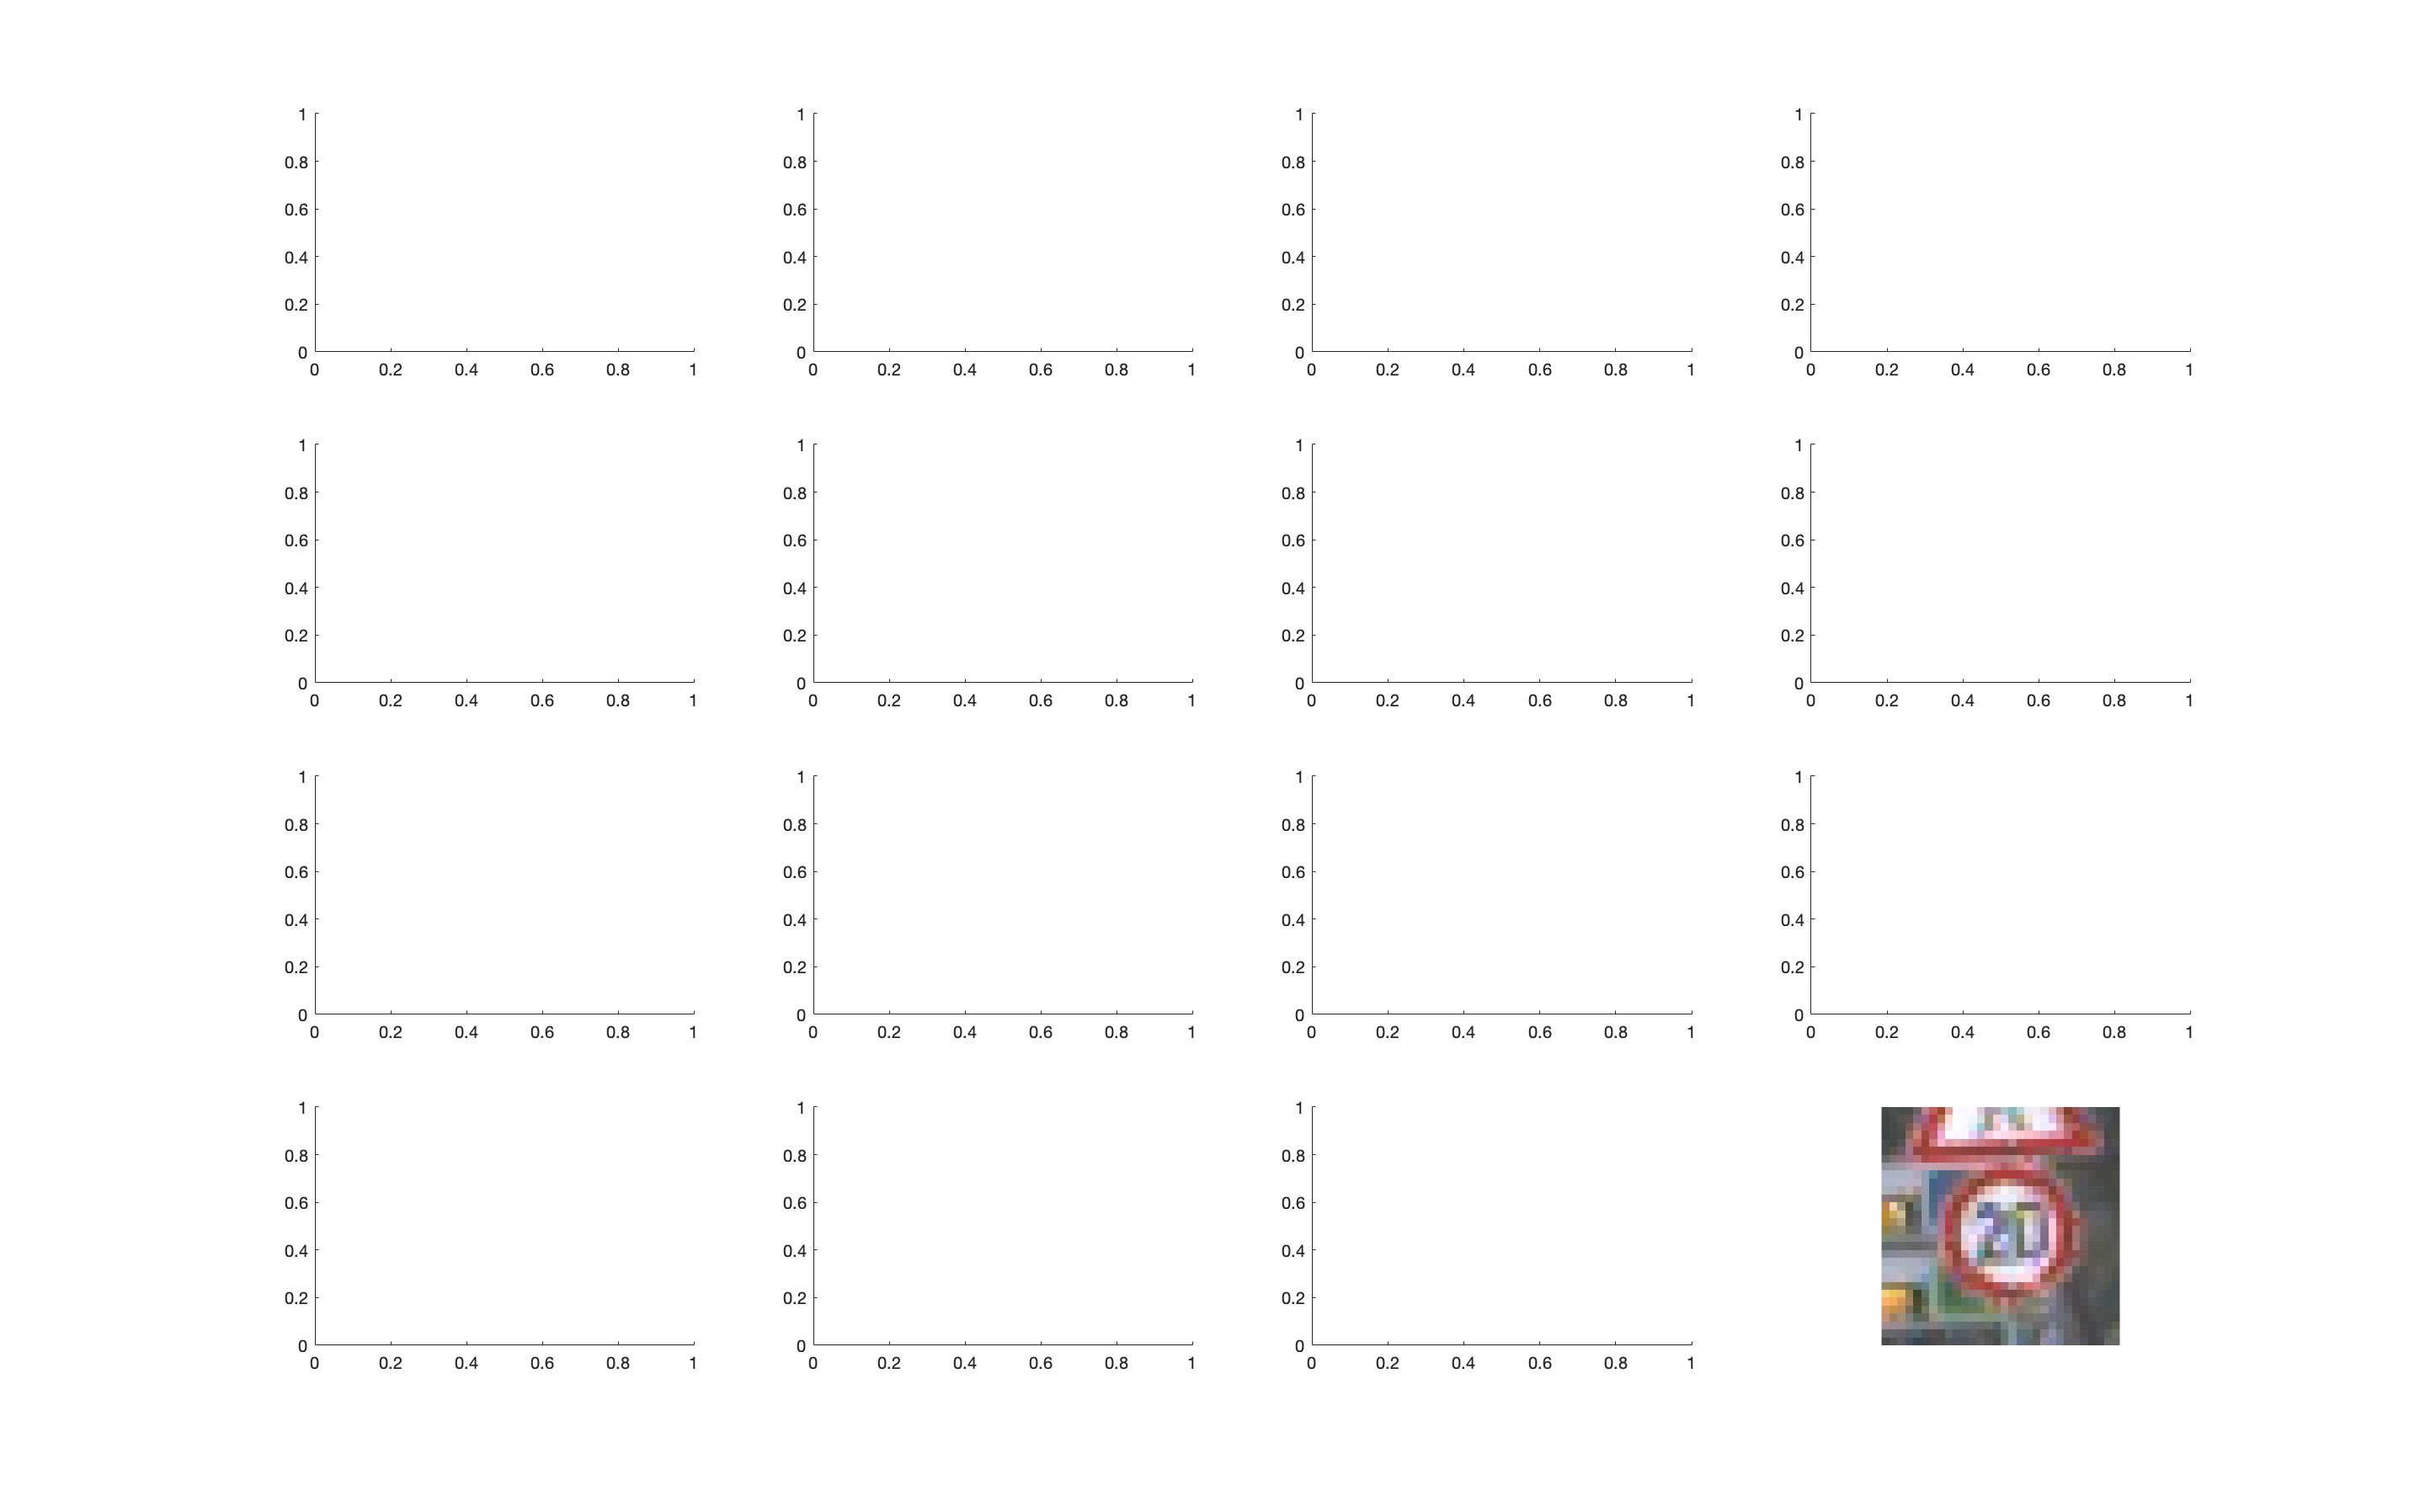

image_features = 1×1944 single row vector
    69    76    75    78   104   185   192   152   223   255    65    74    84    96   133   164   173   186   255   255    63    71    81   115   165   167   195   220   250   255    62    69    76   140   200   160   193   241   255   255    69    69    84   166   192   153   208   255   227   234


image_features = 1×1944 single row vector
    69    76    75    78   104   185   192   152   223   255    65    74    84    96   133   164   173   186   255   255    63    71    81   115   165   167   195   220   250   255    62    69    76   140   200   160   193   241   255   255    69    69    84   166   192   153   208   255   227   234


Unable to perform assignment because the size of the left side is 1-by-1765 and the size of the right side is 1-by-1945.

bag_of_features = [];

for k = 0:42
    folder = "./images/train/" + int2str(k);
    folder = convertStringsToChars(folder);
    file_type = fullfile(folder, "*.png");
    files = dir(file_type);
    
    for idx = 1:length(files)
        name_folder = files(idx).name;
        file_name = fullfile(files(idx).folder, name_folder);
        
        image = imread(file_name); % read image
        imshow(image)
        image_features = processar_imatge(image)
        image_features
        % bof = [histRedTop, histBlueTop, histRedBot, histBlueBot, hog, k]

        bag_of_features(idx,:) = [image_features, k];
    end
end

bag_of_features